%DEMO_ART Demonstrates the use of, and results from, the ART methods
%
% This script illustrates the use of the ART methods Kaczmarz, symmetric
% Kaczmarz, and randomized Kaczmarz.
%
% The script creates a parallel-beam CT test problem and solves it with the
% ART methods.  The exact image and the results from the methods are shown.
%
% See also: demo_cart, demo_constraints, demo_custom_all, demo_matrixfree,
% demo_relaxpar, demo_sirt, demo_stoprules, demo_training.

% Code written by: Per Christian Hansen, Jakob Sauer Jorgensen, and 
% Maria Saxild-Hansen, 2010-2017.

% This file is part of the AIR Tools II package and is distributed under
% the 3-Clause BSD License. A separate license file should be provided as
% part of the package. 
% 
% Copyright 2017 Per Christian Hansen, Technical University of Denmark and
% Jakob Sauer Jorgensen, University of Manchester.

clear, clc
fprintf(1,'Starting demo_art:\n\n');

Starting demo_art:




% Set the parameters for the test problem.
N = 50;           % The image is N-times-N..
phi = 0:2:178;  % No. of used angles.
p = 75;           % No. of parallel rays.

fprintf(1,'Creating a parallel-beam tomography test problem\n');

Creating a parallel-beam tomography test problem


fprintf(1,'with N = %2.0f, theta = %1.0f:%1.0f:%3.0f, and p = %2.0f.',...
    [N,phi(1),phi(2)-phi(1),phi(end),p]);

with N = 50, theta = 0:2:178, and p = 75.

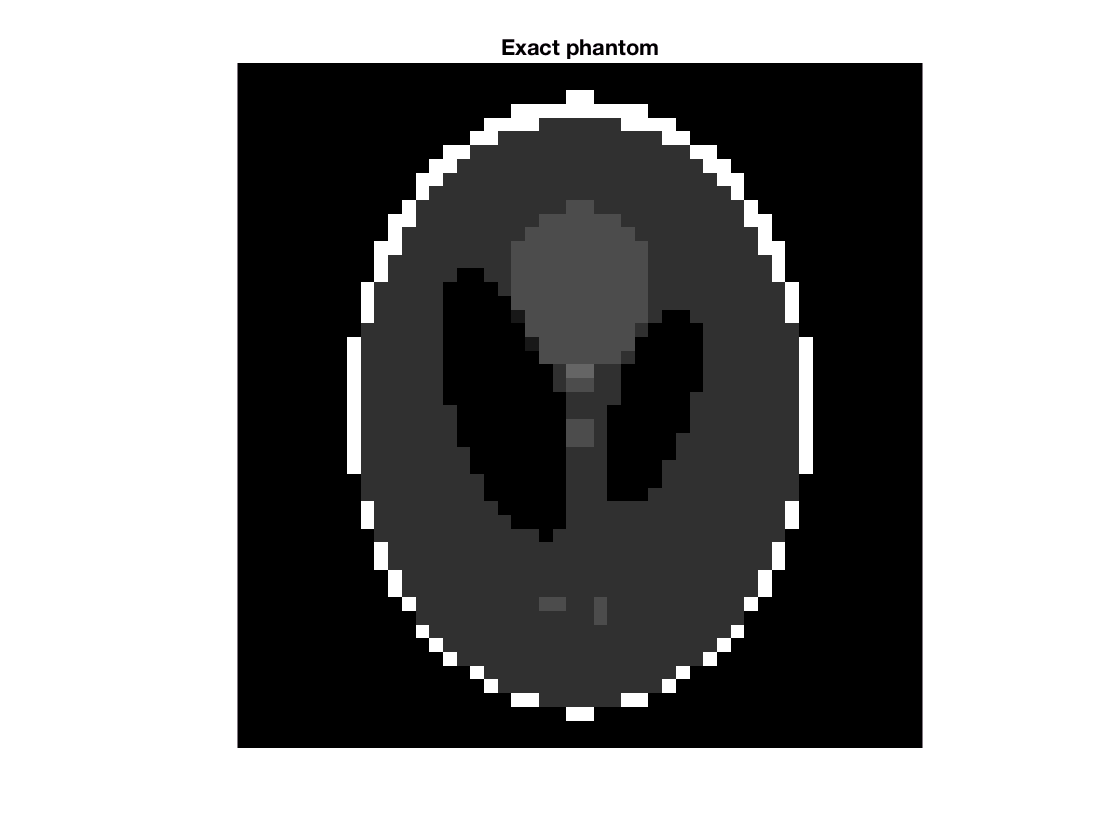


% Create the test problem.
[A,b,x] = paralleltomo(N,phi,p);

% Show the exact solution.
figure(1), clf
subplot()
% subplot(2,2,1)
imagesc(reshape(x,N,N)), colormap gray, axis image off
c = caxis;
title('Exact phantom')

fprintf(1, 'sparsity: %d', sum(x == 0))

sparsity: 1482

fprintf(1,'\n\n');


x0 = zeros(N ^ 2, 1);

## Necessary calculation for RSK

tic
cov_A = cov(A); % expensive
eig_cov_A = eig(cov_A); % expensive too!
min_eig = min(eig_cov_A(eig_cov_A > 0));
ita = @(t, theta) (1 + t * min_eig) ^ (-theta);
toc  % approx 4 min

Elapsed time is 460.566615 seconds.


## Iteration settings

k = [3, 6, 9];           % Number of iterations.
theta = 1;
run_robust = @(type, theta) art(type,A,b,k,x0,struct('verbose', 10,'waitbar',true,'ita', ita, 'theta', theta, 'robust', true));
run_general = @(type, theta) art(type,A,b,k,x0,struct('verbose', 10,'waitbar',true,'ita', ita, 'theta', theta));
run_special = @(type) art(type,A,b,k,x0,struct('verbose', 10,'waitbar',true));
plotter = Plotter(x, N, c, k, true);

## Perform the Kaczmarz iterations.

% type = 'kaczmarz';
% [Xrand, info] = run_special(type);
% plotter.plot(Xrand, type);

## Perform the randomized Kaczmarz iterations.

% type = 'randkaczmarz';
% [Xrand, info] = run_special(type);
% plotter.plot(Xrand, type);

## SK

% type = 'SK';
% [Xrand, info] = run_special(type);
% plotter.plot(Xrand, type);

## The special RSK in [26]

% type = 'RSK';
% [Xrand, info] = run_special(type);
% plotter.plot(Xrand, type)

## Generalized RSK

type = 'RSK';
[Xrand, info] = run_general(type,1);

using customized ita

t = 1

    1/30000:  resnorm=1.73e+01  relaxpar=1.00e+00  time(iter/total)=5.76e-01/3.81e+00 secs.
   11/30000:  resnorm=6.89e-01  relaxpar=1.00e+00  time(iter/total)=2.53e-01/7.02e+00 secs.
   21/30000:  resnorm=2.58e-01  relaxpar=1.00e+00  time(iter/total)=2.82e-01/9.77e+00 secs.
   31/30000:  resnorm=1.45e-01  relaxpar=1.00e+00  time(iter/total)=8.27e-01/1.42e+01 secs.
   41/30000:  resnorm=9.97e-02  relaxpar=1.00e+00  time(iter/total)=8.17e-01/1.97e+01 secs.
   51/30000:  resnorm=7.77e-02  relaxpar=1.00e+00  time(iter/total)=4.49e-01/2.44e+01 secs.
   61/30000:  resnorm=6.37e-02  relaxpar=1.00e+00  time(iter/total)=3.20e-01/2.76e+01 secs.
   71/30000:  resnorm=5.36e-02  relaxpar=1.00e+00  time(iter/total)=3.98e-01/3.19e+01 secs.
   81/30000:  resnorm=4.61e-02  relaxpar=1.00e+00  time(iter/total)=2.28e-01/3.53e+01 secs.
   91/30000:  resnorm=3.94e-02  relaxpar=1.00e+00  time(iter/total)=6.22e-01/3.85e+01 secs.
  101/30000:  resnorm=3.48e-02  relaxpar=1.00e+00  time(iter/total)=2.68e-01/4.1

Relative error = 0.000 %
sparsity = 1448
sparsity_acc = 97.706 %


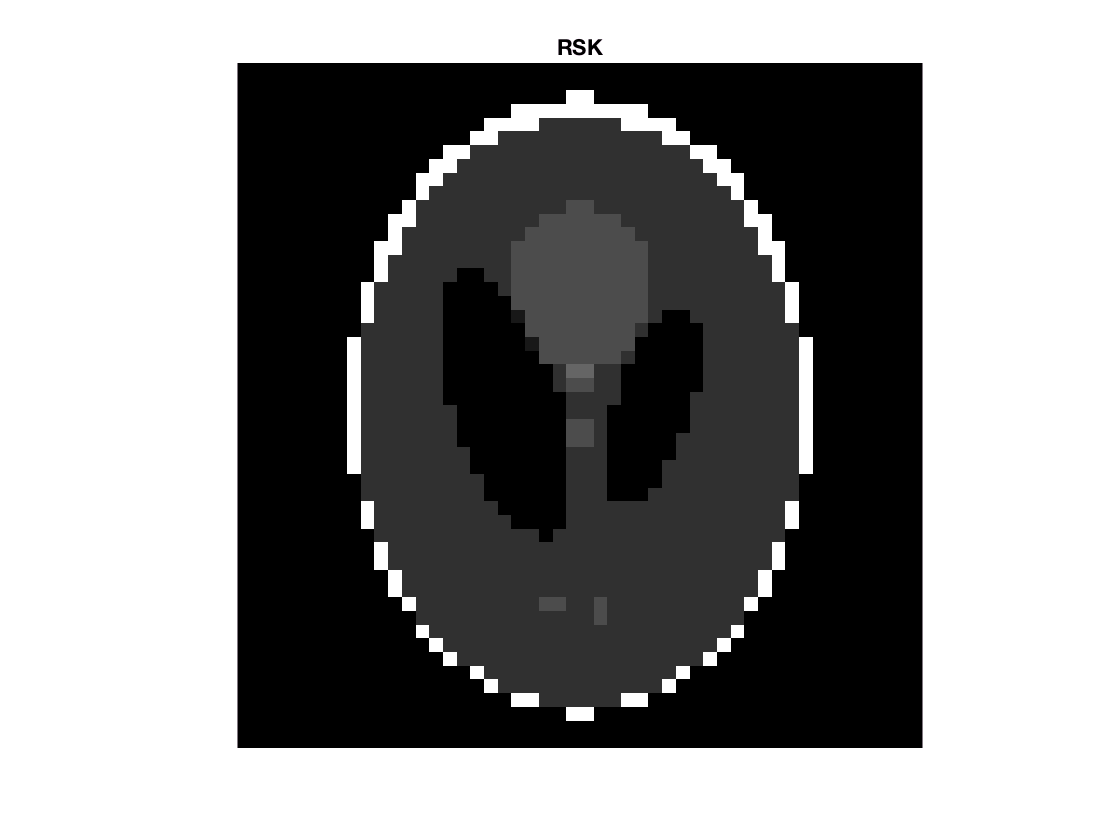

plotter.plot(Xrand, 'Generalized RSK')

## Generalized RSK with theta = 0.5 

type = 'RSK';
[Xrand, info] = run_general(type,1);

using customized ita

t = 1

1/3:  resnorm=1.65e+01  relaxpar=1.00e+00  time(iter/total)=4.77e-01/2.73e+00 secs.
3/3:  resnorm=4.30e+00  relaxpar=1.00e+00  time(iter/total)=4.70e-01/3.94e+00 secs.


Relative error = 9.790 %
sparsity = 1369
sparsity_acc = 92.375 %


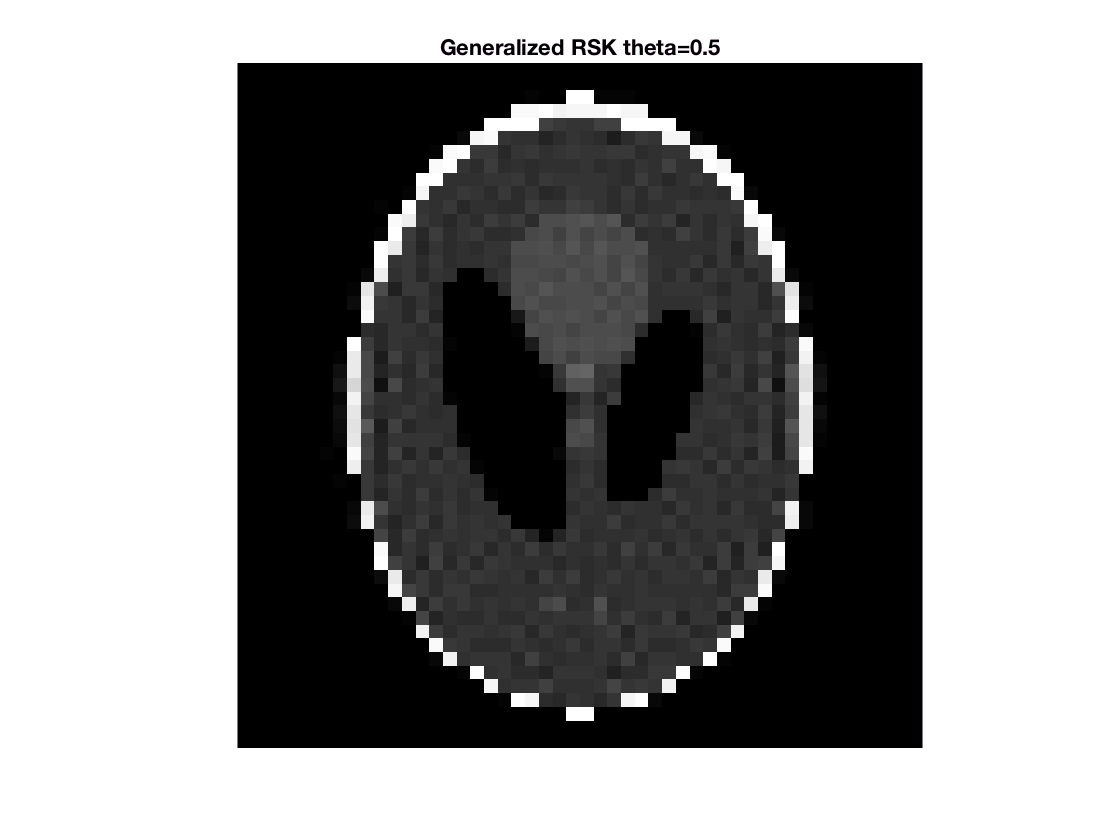

plotter.plot(Xrand, 'Generalized RSK theta=0.5')

## Robust RSK

type = 'RSK';
[Xrand, info] = run_robust(type,1);

using customized ita

t = 1

1/9:  resnorm=3.65e+01  relaxpar=1.00e+00  time(iter/total)=1.48e+00/3.39e+00 secs.
9/9:  resnorm=2.68e+00  relaxpar=1.00e+00  time(iter/total)=6.19e-01/1.20e+01 secs.


Relative error = 14.165 %
sparsity = 1306
sparsity_acc = 1340.000 %
sparsity = 1343
sparsity_acc = 88.124 %
sparsity = 9.041835e+01
sparsity_acc = 90.621 %


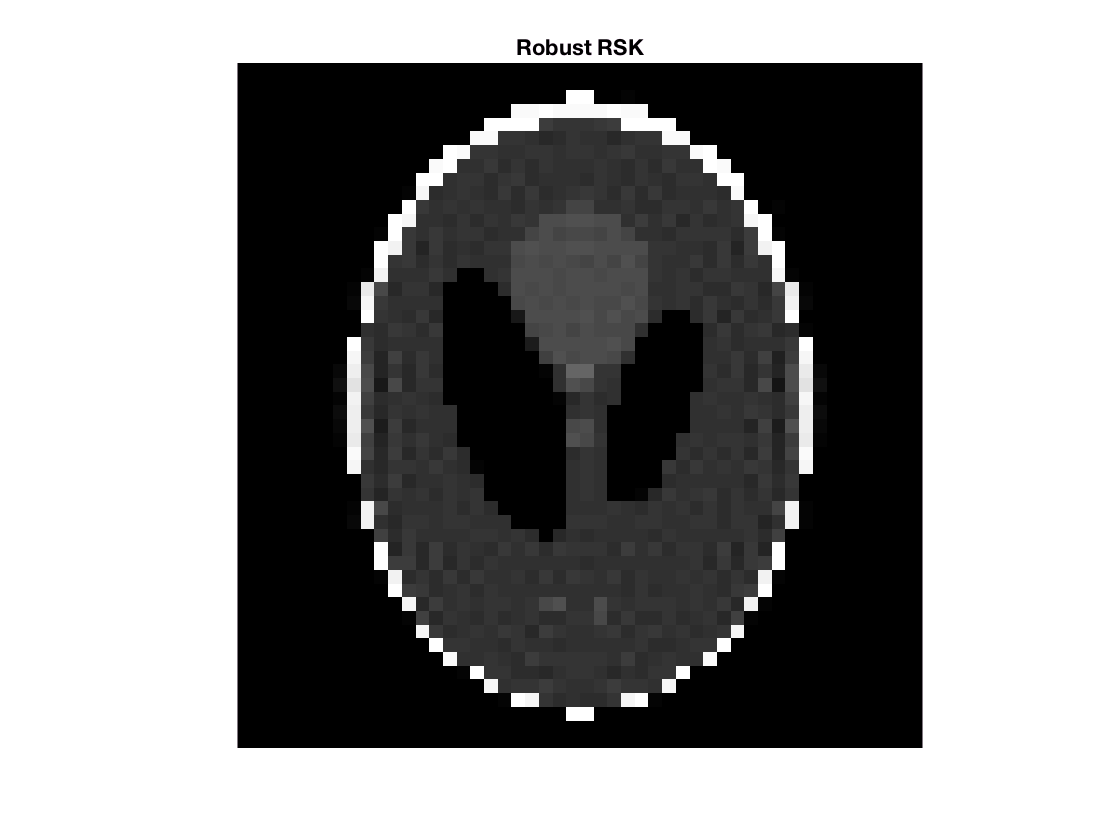

plotter.plot(Xrand, 'Robust RSK')